# COVID-19 Detection Usign X-Rays

by Joshua Rothe

## Image pre-processing, K-Means

K = 3;  % for K-means

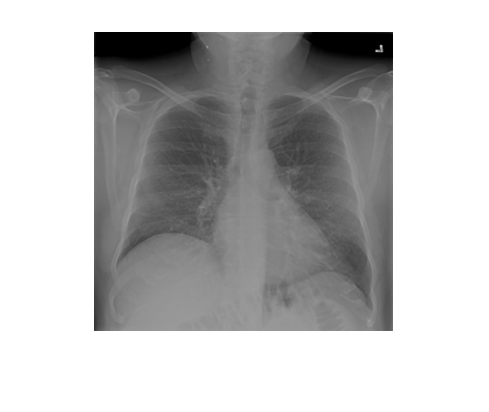

% Class - normal images
num_images = 2000; % Number of images in train dataset is 1-8000
normal_img = zeros((299*299),num_images);   % Initialize empty array
for i = 1:num_images
    filename = sprintf('./train_data/normal/Normal-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    % img = imsegkmeans(img,K);
    normal_img(:,i) = double(reshape(img,[],1));    % reshapes image as column vector
end                                                 % and adds it to normal_img
labels(1:num_images,1) = "normal";
imshow(img);

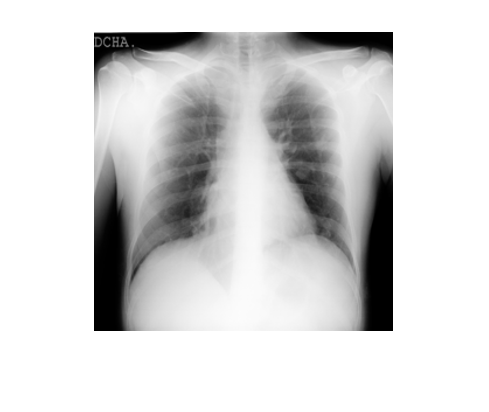

% Class - COVID
num_images2 = 1000; % Number of images in training dataset is 1-3000
cov_img = zeros((299*299),num_images2);  % Initialize empty array
for i = 1:num_images2
    filename = sprintf('./train_data/COVID/COVID-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    % img = imsegkmeans(img,K);
    cov_img(:,i) = double(reshape(img,[],1));       % reshapes image as column vector
end                                                 % and adds it to cov_img
labels(num_images+1:num_images2+num_images,1) = "COVID";
imshow(img);

% Combine images and labels
train_images = [normal_img, cov_img];
train_labels = labels;

## Apply PCA

%% Train and find the PCA dimensions of the training data
% First reduce the training data to a computationally manageable size
% (note: in this instance, size is unchanged, but may adjust as needed)
train_size = num_images + num_images2;
base = 50;         % Base size, given
% Reduced variables are for if we reduce the number if pics taken from
% dataset.
train_images_reduced = train_images(:,[1:train_size]);
train_labels_reduced = train_labels([1:train_size],:);
% Normalize the data, will be calling it X for simplicity
X = train_images_reduced;
Xmean = mean(X);    % mean of X
Xnorm = X - Xmean;  % normalized
% Calculate covariance matrix
covar_matrix = (Xnorm' * Xnorm) / (train_size - 1);
% Calculate Eigenvectors and Eigenvalues of Covariance Matrix
[Xeivec, Xeival] = eig(covar_matrix);
% Now project the dataset
proj_train = Xnorm * Xeivec;
% Back into larger data format
Xnormk_train = proj_train * Xeivec';

## Create Models

error = 0.3200

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.11567 |      407.87 |     0.11567 |     0.11567 |     onevsone |     0.062751 |       769.04 |


|    2 | Accept |     0.34267 |      264.63 |     0.11567 |      0.1269 |     onevsone |      0.92423 |    0.0038848 |


|    3 | Best   |       0.115 |       436.3 |       0.115 |     0.11512 |     onevsall |    0.0012233 |       64.763 |


|    4 | Accept |     0.34267 |      280.16 |       0.115 |     0.11518 |     onevsall |    0.0017944 |    0.0047939 |


|    5 | Accept |       0.117 |      416.94 |       0.115 |     0.11502 |     onevsall |      0.90061 |       191.08 |


|    6 | Accept |       0.117 |      418.29 |       0.115 |     0.11503 |     onevsone |       359.11 |       55.194 |


|    7 | Accept |       0.117 |      441.05 |       0.115 |     0.11504 |     onevsone |      0.12838 |       207.19 |


|    8 | Accept |     0.13233 |      428.42 |       0.115 |     0.11504 |     onevsall |    0.0023193 |       996.59 |


|    9 | Accept |     0.11667 |       654.3 |       0.115 |     0.11503 |     onevsone |       0.8318 |       7.2021 |


|   10 | Accept |     0.11667 |      550.33 |       0.115 |     0.11503 |     onevsone |       8.4719 |       16.455 |


|   11 | Accept |       0.117 |      440.65 |       0.115 |     0.11534 |     onevsall |       25.872 |       86.929 |


|   12 | Accept |       0.117 |      434.21 |       0.115 |     0.11541 |     onevsone |       986.25 |       998.81 |


|   13 | Best   |     0.11467 |      426.32 |     0.11467 |     0.11474 |     onevsall |    0.0010908 |        107.7 |


|   14 | Accept |     0.11467 |      422.95 |     0.11467 |      0.1147 |     onevsall |    0.0011116 |          110 |


|   15 | Accept |     0.11533 |      418.19 |     0.11467 |     0.11488 |     onevsall |    0.0011608 |       108.63 |


|   16 | Accept |       0.117 |      540.09 |     0.11467 |     0.11492 |     onevsone |    0.0010035 |       22.971 |


|   17 | Accept |       0.117 |      427.95 |     0.11467 |     0.11551 |     onevsall |    0.0010596 |       95.842 |


|   18 | Accept |       0.122 |      444.71 |     0.11467 |     0.11549 |     onevsone |    0.0011256 |       462.33 |


|   19 | Accept |       0.117 |      523.85 |     0.11467 |     0.11534 |     onevsall |     0.002023 |       18.661 |


|   20 | Accept |       0.117 |      447.56 |     0.11467 |     0.11562 |     onevsall |     0.007775 |       46.565 |


|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|   21 | Accept |     0.11767 |      444.16 |     0.11467 |     0.11584 |     onevsall |    0.0024884 |       58.461 |


|   22 | Accept |     0.11567 |      661.76 |     0.11467 |     0.11581 |     onevsall |       16.761 |       4.0342 |


|   23 | Accept |     0.11633 |      671.67 |     0.11467 |     0.11581 |     onevsall |       7.3108 |       7.0045 |


|   24 | Accept |       0.117 |      678.25 |     0.11467 |      0.1158 |     onevsall |    0.0013265 |       6.1045 |


|   25 | Accept |     0.11933 |      687.14 |     0.11467 |      0.1158 |     onevsall |    0.0012653 |       2.2277 |


|   26 | Accept |     0.34267 |      278.64 |     0.11467 |     0.11562 |     onevsone |       548.64 |      0.10832 |


|   27 | Accept |       0.117 |      573.29 |     0.11467 |     0.11562 |     onevsone |       543.79 |       10.878 |


|   28 | Accept |       0.116 |      430.23 |     0.11467 |     0.11562 |     onevsone |    0.0012414 |       104.79 |


|   29 | Accept |       0.117 |      399.42 |     0.11467 |     0.11584 |     onevsall |    0.0019021 |       125.79 |


|   30 | Accept |       0.117 |      442.91 |     0.11467 |     0.11584 |     onevsone |       0.4576 |       104.24 |


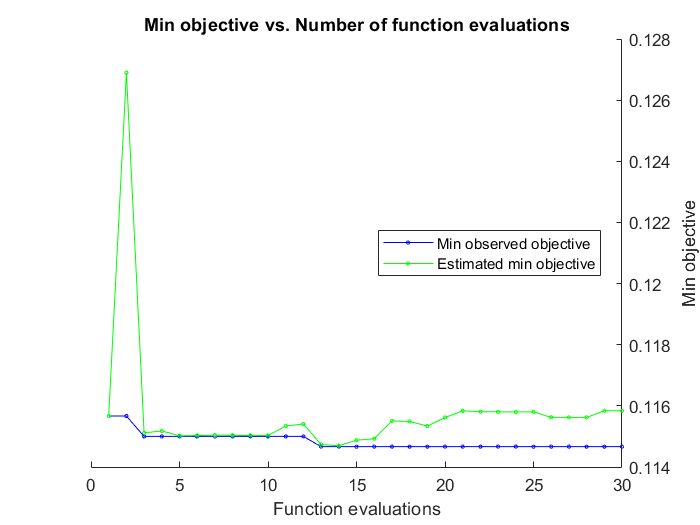


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 14128.3376 seconds.
Total objective function evaluation time: 14092.2198

Best observed feasible point:
     Coding     BoxConstraint    KernelScale
    ________    _____________    ___________

    onevsall      0.0010908         107.7   

Observed objective function value = 0.11467
Estimated objective function value = 0.11584
Function evaluation time = 426.3178

Best estimated feasible point (according to models):
     Coding     BoxConstraint    KernelScale
    ________    _____________    ___________

    onevsall      0.0010908         107.7   

Estimated objective function value = 0.11584
Estimated function e

% Create a model with standard params
Mdl = fitcecoc(Xnormk_train',train_labels_reduced');
% Note: This model performs poorly. More than 50% error when 
% tested using predict().
error = resubLoss(Mdl)  % resubloss error

% Cross validate, obtain better model performance
t = templateSVM('Standardize',true);
Mdl2 = fitcecoc(Xnormk_train',train_labels_reduced',...
    'Learners',t,'ClassNames',{'normal','COVID'});
% Mdl2 had about 85% accuracy when tested, much better than Mdl
options = statset('UseParallel',true);
CVMdl = crossval(Mdl2,'Options',options);

kFoldError = kfoldLoss(CVMdl) % kfoldloss error from cross validated model

kFoldError = 0.1233

## Test Models

% Return a vector of predicted values, should all be non-COVID.
% test data is 8001 - 8100
clear test_label_healthy; clear test_data_healthy; k = 1;
%test_data_healthy = zeros((299*299),(8100-8001+1));   % Initialize empty array
for i = 8001:8100
    filename = sprintf('./test_data/normal/Normal-%i.png', i);
    img = (imread(filename));
    test_data_healthy(:,k) = double(reshape(img,[],1));    % reshapes image as column vector
    k = k + 1;  % increment k for matrix pos
end
[test_label_healthy] = predict(Mdl2,test_data_healthy');

% Check performance by counting number of times correct value was reached
perf_healthy_temp = categorical(test_label_healthy);
labels_perf = categories(perf_healthy_temp) % displlays labels

labels_perf = 2×1 cell array
    {'COVID' }
    {'normal'}


perf_healthy = countcats(perf_healthy_temp) % displays occurance per label

perf_healthy =     11
    89


% E.g. for 11 COVID entries and 89 normal entries, the model is 89%
% accurate

% Return a vector of predicted values, should all be all COVID infections.
% test data is 3001 - 3100
clear test_label_covid; clear test_data_covid; k = 1;
%test_data_covid = zeros((299*299),(3101-3001+1));   % Initialize empty array
for i = 3001:3100
    filename = sprintf('./test_data/COVID/COVID-%i.png', i);
    img = (imread(filename));
    test_data_covid(:,k) = double(reshape(img,[],1));    % reshapes image as column vector
    k = k + 1;  % increment k for matrix pos
end
[test_label_covid] = predict(Mdl2,test_data_covid');

% Check performance by counting number of times correct value was reached
perf_covid_temp = categorical(test_label_covid);
labels_perf2 = categories(perf_covid_temp) % displlays labels

labels_perf2 = 2×1 cell array
    {'COVID' }
    {'normal'}


perf_covid = countcats(perf_covid_temp) % displays occurance per label

perf_covid =     19
    81


% E.g. for 19 normal entries and 81 COVID entries, the model is 81%
% accurate